clc; clear all; close all;
%sympref('FloatingPointOutput',true);

## Quintic Trajectory Generation Points

P0=[0 ;0;0];P1=[0 ;0 ;1];P2=[1;0;1];P3=[1;1;1];P4=[0;1;1];P5=[0;0;1];
%Calc Coefficents - P1-5 have the same A mat, P01 has different A mat
t0 = 0;
tfP01 = 5;
tf = 15;
trajec_one = [];
trajec_two = [];
trajec_three = [];
trajec_four = [];
trajec_five = [];

vel_one = []


vel_one =

     []



vel_two = []


vel_two =

     []



vel_three = []


vel_three =

     []



vel_four = []


vel_four =

     []



vel_five = []


vel_five =

     []




syms t
trajPoint1 = calcTraj(t0,tfP01,P0,P1)

$$trajPoint1 = \left[\begin{array}{ccc} 0 & 0 & 0.0800\,t^{3}-0.0240\,t^{4}+0.0019\,t^{5} \end{array}\right]$$

vel1 = diff(trajPoint1,t)

$$vel1 = \left[\begin{array}{ccc} 0 & 0 & 0.2400\,t^{2}-0.0960\,t^{3}+0.0096\,t^{4} \end{array}\right]$$

acc1 = diff(trajPoint1,t,2)

$$acc1 = \left[\begin{array}{ccc} 0 & 0 & 0.4800\,t-0.2880\,t^{2}+0.0384\,t^{3} \end{array}\right]$$

%diff(trajPoint1,t,2)
tfP01 = 15;
trajPoint2 = calcTraj(t0,tfP01,P1,P2)

$$trajPoint2 = \left[\begin{array}{ccc} 0.0030\,t^{3}-2.9630e-04\,t^{4}+7.9012e-06\,t^{5} & 0 & 1 \end{array}\right]$$

vel2 = diff(trajPoint2,t)

$$vel2 = \left[\begin{array}{ccc} 0.0089\,t^{2}-0.0012\,t^{3}+3.9506e-05\,t^{4} & 0 & 0 \end{array}\right]$$

acc2 = diff(trajPoint2,t,2)

$$acc2 = \left[\begin{array}{ccc} 0.0178\,t-0.0036\,t^{2}+1.5802e-04\,t^{3} & 0 & 0 \end{array}\right]$$

%diff(trajPoint2,t,2)
trajPoint3 = calcTraj(t0,tfP01,P2,P3)

$$trajPoint3 = \left[\begin{array}{ccc} 1 & 0.0030\,t^{3}-2.9630e-04\,t^{4}+7.9012e-06\,t^{5} & 1 \end{array}\right]$$

vel3 = diff(trajPoint3,t)

$$vel3 = \left[\begin{array}{ccc} 0 & 0.0089\,t^{2}-0.0012\,t^{3}+3.9506e-05\,t^{4} & 0 \end{array}\right]$$

acc3 = diff(trajPoint3,t,2)

$$acc3 = \left[\begin{array}{ccc} 0 & 0.0178\,t-0.0036\,t^{2}+1.5802e-04\,t^{3} & 0 \end{array}\right]$$

%diff(trajPoint3,t,2)
trajPoint4 = calcTraj(t0,tfP01,P3,P4)

$$trajPoint4 = \left[\begin{array}{ccc} 1-0.0030\,t^{3}+2.9630e-04\,t^{4}-7.9012e-06\,t^{5} & 1 & 1 \end{array}\right]$$

vel4 = diff(trajPoint4,t)

$$vel4 = \left[\begin{array}{ccc} -0.0089\,t^{2}+0.0012\,t^{3}-3.9506e-05\,t^{4} & 0 & 0 \end{array}\right]$$

acc4 = diff(trajPoint4,t,2)

$$acc4 = \left[\begin{array}{ccc} -0.0178\,t+0.0036\,t^{2}-1.5802e-04\,t^{3} & 0 & 0 \end{array}\right]$$

%diff(trajPoint4,t,2)
trajPoint5 = calcTraj(t0,tfP01,P4,P5)

$$trajPoint5 = \left[\begin{array}{ccc} 0 & 1-0.0030\,t^{3}+2.9630e-04\,t^{4}-7.9012e-06\,t^{5} & 1 \end{array}\right]$$

vel5 = diff(trajPoint5,t)

$$vel5 = \left[\begin{array}{ccc} 0 & -0.0089\,t^{2}+0.0012\,t^{3}-3.9506e-05\,t^{4} & 0 \end{array}\right]$$

acc5 = diff(trajPoint5,t,2)

$$acc5 = \left[\begin{array}{ccc} 0 & -0.0178\,t+0.0036\,t^{2}-1.5802e-04\,t^{3} & 0 \end{array}\right]$$

%diff(trajPoint5,t,2)

t1 = 0:0.5:5;
t2 = 0:0.1:15;

for i = 1:length(t1)
    traj_one = [0, 0, 6*t1(i)^5/3125 - 3*t1(i)^4/125 + 2*t1(i)^3/25];
    trajec_one = [trajec_one;traj_one];
    
    
    vel1 = [0, 0, 0.2400*t1(i)^2 - 0.0960*t1(i)^3 + 0.0096*t1(i)^4]
    vel_one = [vel_one;vel1];

end

vel1 =      0     0     0


vel1 =          0         0    0.0486


vel1 =          0         0    0.1536


vel1 =          0         0    0.2646


vel1 =          0         0    0.3456


vel1 =          0         0    0.3750


vel1 =          0         0    0.3456


vel1 =          0         0    0.2646


vel1 =          0         0    0.1536


vel1 =          0         0    0.0486


vel1 = 	1.0e+-15 *

         0         0   -0.8882


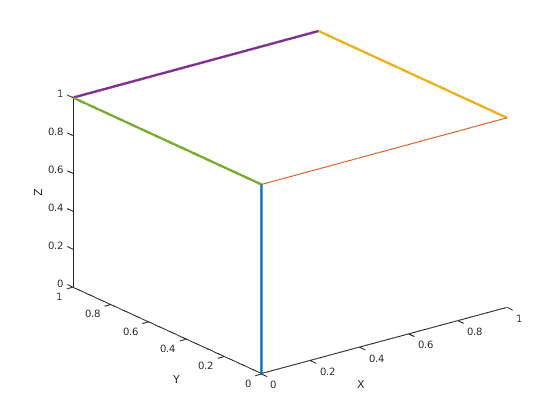


for i = 1:length(t2)

    traj_two = [4664065662093477*t2(i)^5/590295810358705651712 - t2(i)^4/3375 + (2*t2(i)^3)/675, 0, 1];
    trajec_two = [trajec_two;traj_two];

    
    vel2 = [0.0089*t2(i)^2 - 0.0012*t2(i)^3 + 3.9506e-05*t2(i)^4, 0, 0];
    vel_two = [vel_two;vel2];

    traj_three   = [1, 4664065662093477*t2(i)^5/590295810358705651712 - t2(i)^4/3375 + 2*t2(i)^3/675, 1];
    trajec_three = [trajec_three;traj_three];

    vel3 =     [0, 0.0089*t2(i)^2 - 0.0012*t2(i)^3 + 3.9506e-05*t2(i)^4, 0];
    vel_three =[vel_three;vel3];

    traj_four =  [- (4664065662093477*t2(i)^5)/590295810358705651712 + t2(i)^4/3375 - (2*t2(i)^3)/675 + 1, 1, 1];
    trajec_four = [trajec_four;traj_four];

    vel4 = [- 0.0089*t2(i)^2 + 0.0012*t2(i)^3 - 3.9506e-05*t2(i)^4, 0, 0];
    vel_four = [vel_four;vel4];

    traj_five = [0, - (4664065662093477*t2(i)^5)/590295810358705651712 + t2(i)^4/3375 - (2*t2(i)^3)/675 + 1, 1];
    trajec_five = [trajec_five; traj_five];

    vel5 = [0, - 0.0089*t2(i)^2 + 0.0012*t2(i)^3 - 3.9506e-05*t2(i)^4, 0];
    vel_five = [vel_five;vel5];
end
%plot(t2,trajec_five)
p = plot3(trajec_one(:,1),trajec_one(:,2),trajec_one(:,3));
p.LineWidth = 3;
hold on;
plot3(trajec_two(:,1),trajec_two(:,2),trajec_two(:,3));
p.LineWidth = 3;

p = plot3(trajec_three(:,1),trajec_three(:,2),trajec_three(:,3));
p.LineWidth = 3;

p = plot3(trajec_four(:,1),trajec_four(:,2),trajec_four(:,3));
p.LineWidth = 3;

x = plot3(trajec_five(:,1),trajec_five(:,2),trajec_five(:,3));
x.LineWidth = 3;
xlabel('X')
ylabel('Y')
zlabel('Z')
hold off;

% p  = plot3(vel_one(:,1),vel_one(:,2),vel_one(:,3));
% hold on;
% p  = plot3(vel_two(:,1),vel_two(:,2),vel_two(:,3));
% p  = plot3(vel_three(:,1),vel_three(:,2),vel_three(:,3));
% p  = plot3(vel_four(:,1),vel_four(:,2),vel_four(:,3));
% p  = plot3(vel_five(:,1),vel_five(:,2),vel_five(:,3));
% p.LineWidth = 3;
hold off;

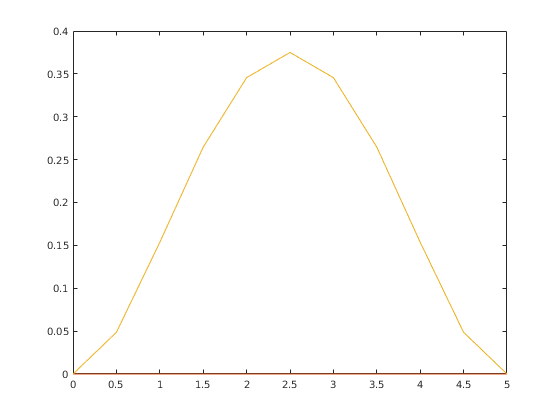

plot(t1,vel_one);

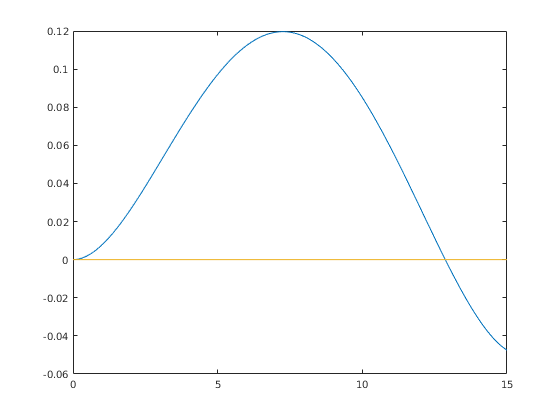

plot(t2,vel_two);

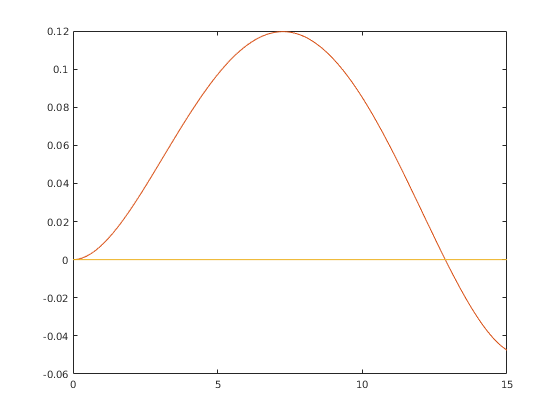

plot(t2,vel_three);

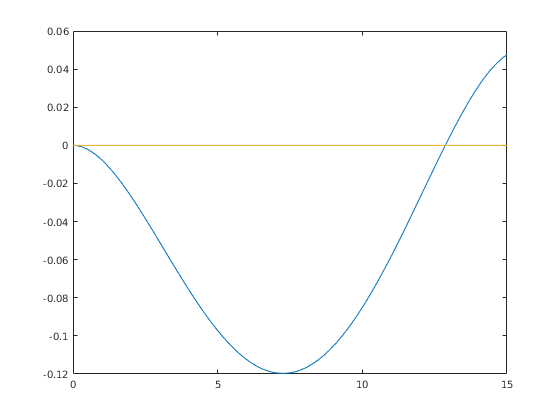

plot(t2,vel_four);

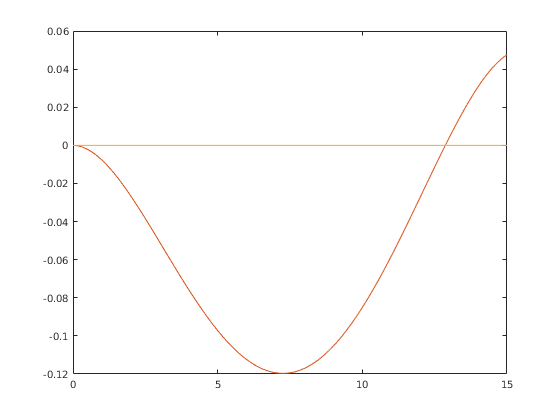

plot(t2,vel_five);

function ret = calcTraj(t0,tf,P0,PF)
    syms t
    Amat = [1 t0 t0^2 t0^3 t0^4 t0^5;
        0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
        0 0 2 6*t0 12*t0^2 20*t0^3;
        1 tf tf^2 tf^3 tf^4 tf^5;
        0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
        0 0 2 6*tf 12*tf^2 20*tf^3];
    
    b = [inv(Amat)*[P0(1);0;0;PF(1);0;0], inv(Amat)*[P0(2);0;0;PF(2);0;0], inv(Amat)*[P0(3);0;0;PF(3);0;0]];
   
    A = [1 t t^2 t^3 t^4 t^5];
  

    ret = A*b; 
end